%clear all
%Runs the Tracking Algorithm using the inputs of the select_area_
%Callback and the frame select input

%Load data
clear
close all %to make sure only the data from this time is shown
%select file
disp('Select -mat file containing ultrasound data\n')

Select -mat file containing ultrasound data\n


fil = uigetfile;            % open dialog box to choose file
data = load(fil);           % load file into struct
%change from struct to 3D matrix
names=fieldnames(data); %extract names of each frame
len=length(names); %find # of frames
[r, c]=size(eval(['data.' names{1}])); %find size of each matrix
mat=zeros(r,c,len); %preallocate
for i=1:len
    mat(:,:,i)=eval(['data.' names{i}]); %enter frame information
end
fprintf([fil ' loaded\n']) %tell user file loaded

e_rlat_2-2.mat loaded


clear i data names %clear variables no longer needed
%convert from RF to amplitude
htf=zeros(r,c,len); %preallocate
for i=1:len
    htf(:,:,i)=hilbert(mat(:,:,i)); %find hilbert transform of each frame
end
hamp=abs(htf); %hamp is the analytic envelope
ctr=5; %compression parameter
amp=20*log10(hamp/ctr); %amplitude in dB


%Create Kernal and St
x1 = 100; y1 = 200; w = 50; h = 250;
%{
% For the GUI

% get st from the handles of the area function
st =
%Get the Template and Target frames/ data from slider
%get handles.f from slider1_Callback
tar=
temp=
%search range
sX=10;
sY=10;
%how much of the ROI to search
%
rX=st.h;
cY=st.w;
%}
initstate = [x1, y1, w, h];
st = state(initstate);
% Put things together in a struct, and check the integrity
%search range
sX=5;
sY=10;
%how much of the ROI to search
rX=h/2;
cY=w/2;
method = [sX, sY, rX, cY];
kn = kernel(method,st);

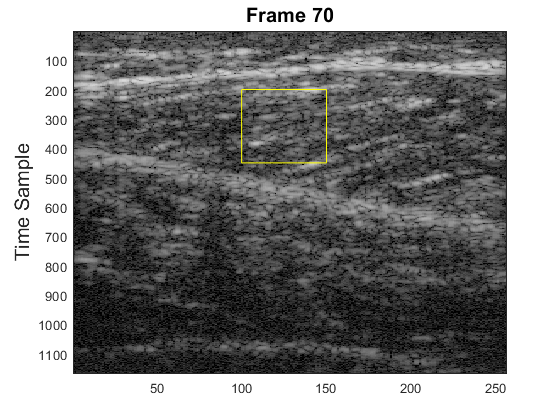


%Frame Selection 
%select start frame
%fprintf('try frame 66 -74 for e_rlat_2-2')
f=input(['Select start frame between 1 and ' num2str(len) ': ']);
if f<1 || f>len
    f=input('Error: select number in range: ');
end
   
    % %display first frame image
    %fprintf(['Displaying frame ' num2str(f) '\n']);
    h=figure;
    i1=image(amp(:,:,f));
    colormap(gray)
    fs=num2str(f);
    title(['Frame ' fs],'FontSize',15)
    ylabel('Time Sample','FontSize',15)
    rectangle('Position',initstate,'EdgeColor','y')

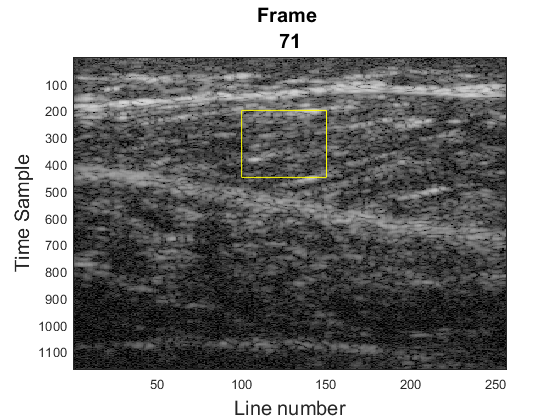

%select 2nd frame
f2=input(['Select 2nd frame between 1 and ' num2str(len) ': ']);
if f2<1 || f2>len
    f2=input('Error: select number in range: ');
end

%fprintf(['Displaying frame ' num2str(f2) '\n']);
h2=figure;
i2=image(amp(:,:,f2));
colormap(gray)
fs2=num2str(f2);
title(["Frame " fs2],'FontSize',15)
xlabel('Line number','FontSize',15)
ylabel('Time Sample','FontSize',15)
rectangle('Position',initstate,'EdgeColor','y')

%generates the Target and template
templ= mat(:,:,f);
tar= mat(:,:,f2);
%Performs NCorr to
data = NCorrEst(templ,tar,st,kn);

%u=x
nonz_u= data.u((data.u ~= 0));
meanu=mean(nonz_u);
disp(["meanu:" meanu])

    "meanu:"    "0.89183"



%v=y
nonz_v= data.v((data.v ~= 0));
meanv=mean(nonz_v);
disp(["meanv:" meanv])

    "meanv:"    "-0.71775"




% Create the quiver
qdata=quiver(data.v, data.u);
disp(["sX " sX "sY " sY] )

    "sX "    "5"    "sY "    "10"



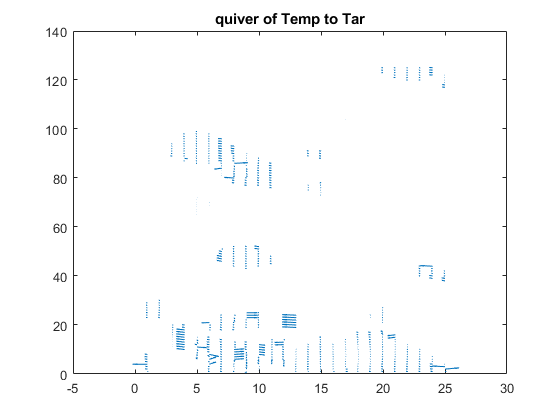

title('quiver of Temp to Tar')